## Load image

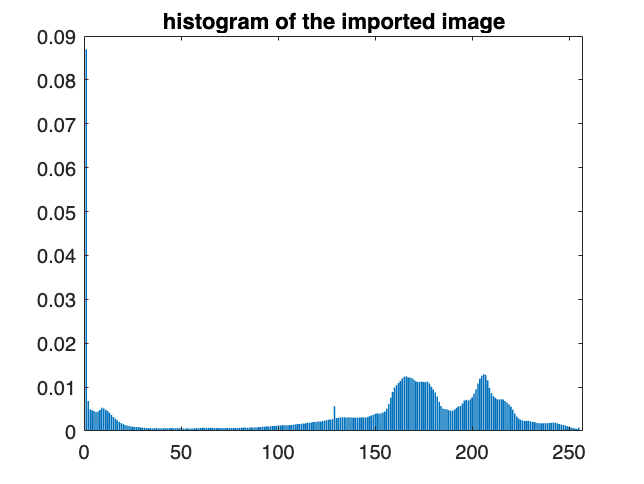

imname = 'me.jpg';

im_all = double(imread(imname));
% Get the grayscale
im = im_all(:,:,1); 
imageSize = size(im);
% Crops the grayscale image im to a square shape 
im = im(1:min(imageSize),1:min(imageSize)); 
imageSize = size(im);

% Compute the histogram
[h_count,h_cent]=imhist(im_all(:,:,1)./256);
h_prob=h_count./numel(im_all(:,:,1));
figure(5)
bar(h_prob)
title('histogram of the imported image')

## Mask creation

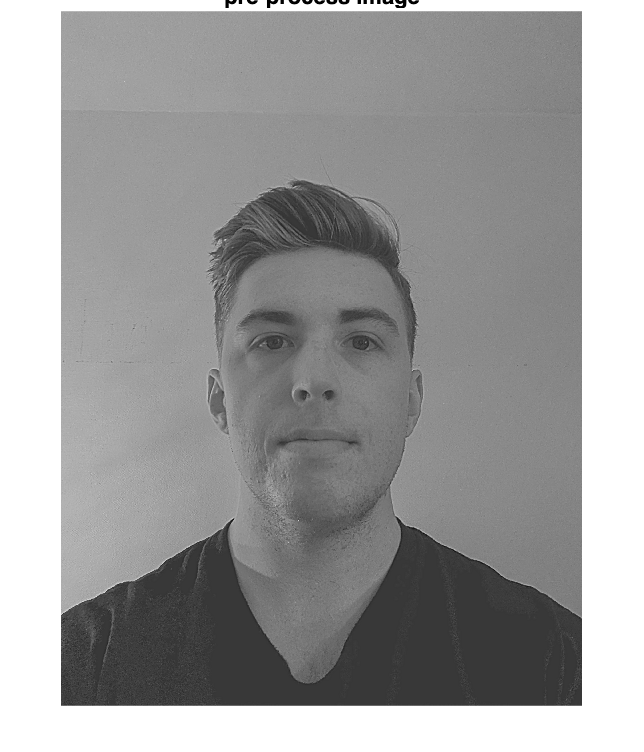

% Options
pre_process='lowpass';
filter_type='built_in_2';

switch pre_process
    case 'lowpass'
        im_l=zeros(size(im_all));
        im_mask=zeros(size(im_all));
        for i=1:3
            sigma=6; % order of the filter
            im_l(:,:,i)=imgaussfilt(im_all(:,:,i),sigma);
            im_mask(:,:,i)=im_all(:,:,i)-im_l(:,:,i);
        end
        %im_all=im_l;
        A=2;
        im_mask=mean(im_mask,3);
        im_all=im_all+im_mask.*A; %A sharp factor
        figure(2)
        imshow(im_all(:,:,1),[])
        title('pre-process image')
        %
        %         im_l=zeros(size(im_all));
        %         for i=1:3
        %             sigma=1; % order of the filter
        %             im_l(:,:,i)=imgaussfilt(im_all(:,:,i),sigma);
        %         end
        %         im_all=im_l;
        %         figure(10)
        %         imshow(im_all(:,:,1),[])
        
    case 'none'
        im_all=im_all;
end

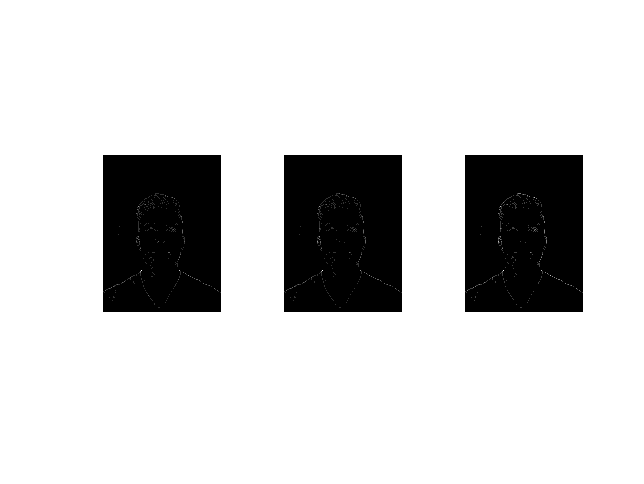

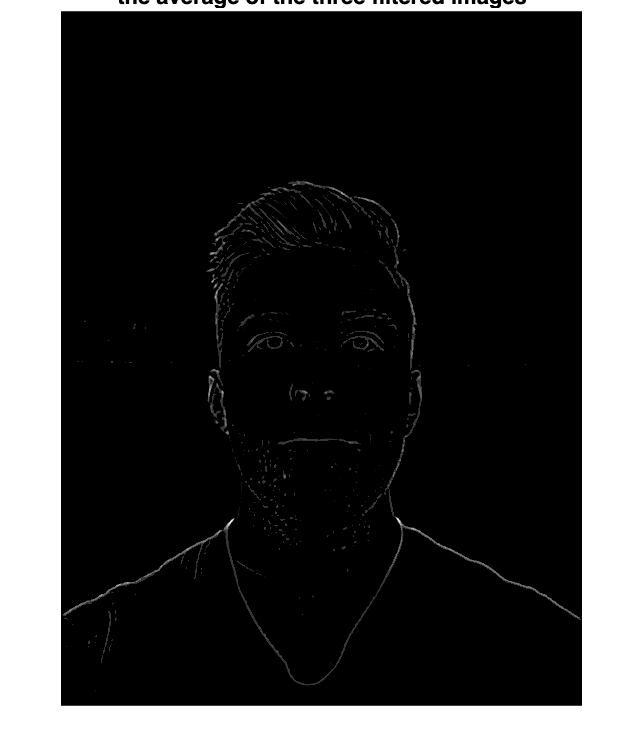


switch filter_type
    case 'built_in_2'
        im_all_new=zeros(size(im_all));
        figure()
        for i=1:3
            im_tmp=im_all(:,:,i);
            h=fspecial('log',60,7);
            %h=fspecial('sobel');
            im_filt_h=imfilter(im_tmp,h);
            im_filt_v=imfilter(im_tmp,h');
            im_filt=im_filt_h+im_filt_v;
            im_filt=uint8(im_filt);
            im_all_new(:,:,i)=im_filt;
            subplot(1, 3, i)
            imshow(im_filt,[])
        
        end
        im_edge=mean(im_all_new,3);
        figure(81)
        imshow(im_edge,[])
        title('the average of the three filtered images')
        
        %         edge_im=edge(im_filt.*200,'prewitt');
        %         figure()
        %         imshow(edge_im,[])
end


disp("Pre_processing: "+pre_process)

Pre_processing: lowpass


disp("Edge detection: "+filter_type)

Edge detection: built_in_2


## Make binary and Imfill

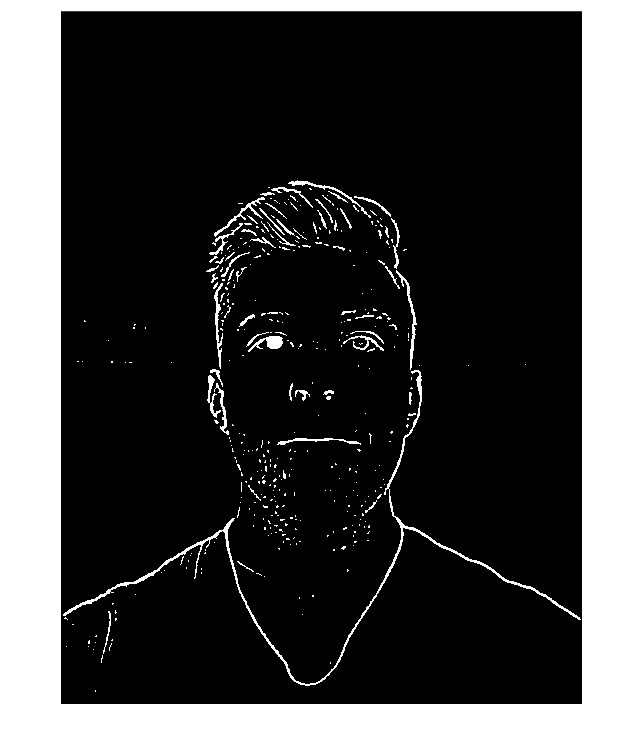

im_edge(im_edge>0)=1;
im_edge((end-10):end,:)=1;
im_edge(:,1:2)=1;
im_edge(:,(end-1):end)=1;
im_fill=uint8(imfill(im_edge,26,'holes'));

figure()
imshow(im_fill,[])

## Bonus

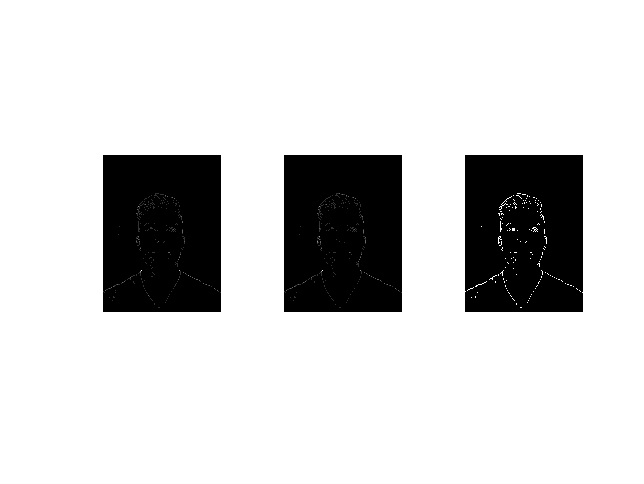

sigma=4;
im_fill_smot=imgaussfilt(im_fill,sigma);
figure(20)
imshow(im_fill_smot,[])
im_fill2=imfill(im_fill_smot);
figure(21)
imshow(im_fill2,[])

## Finalise mask

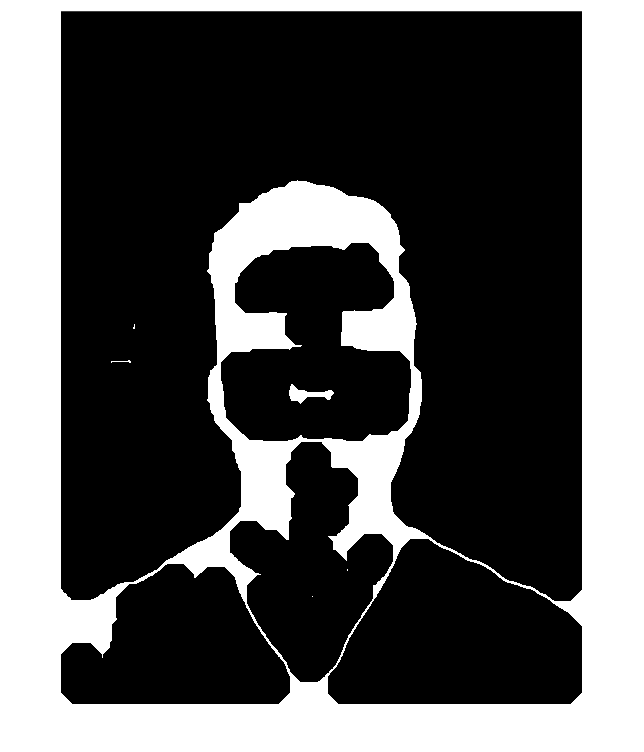

se = strel('disk',100);
im_close=imclose(im_fill2,se);
figure()
imshow(im_close,[])

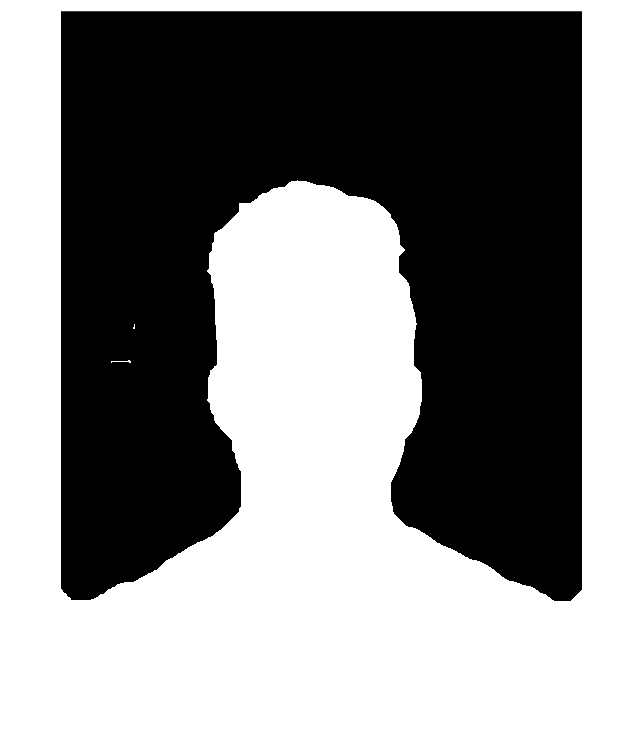


im_fill3=imfill(im_close);
figure()
imshow(im_fill3,[])

## Use mask and blur background

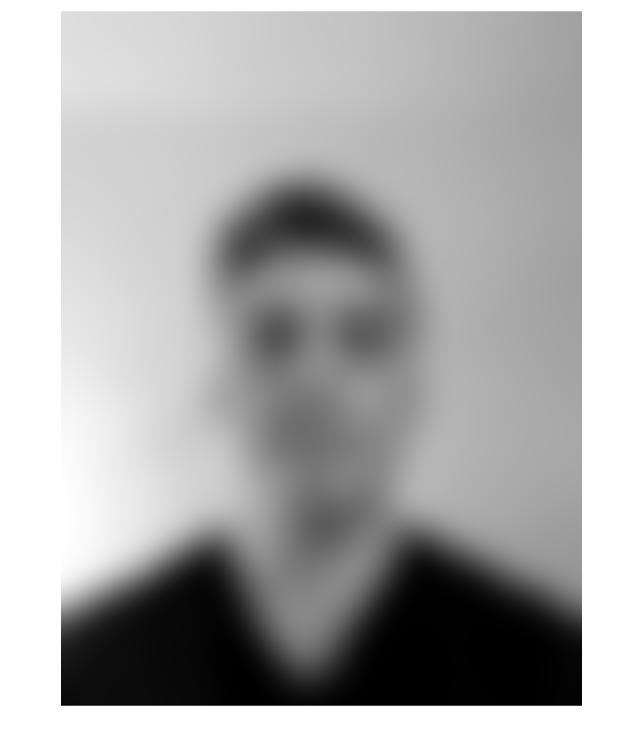

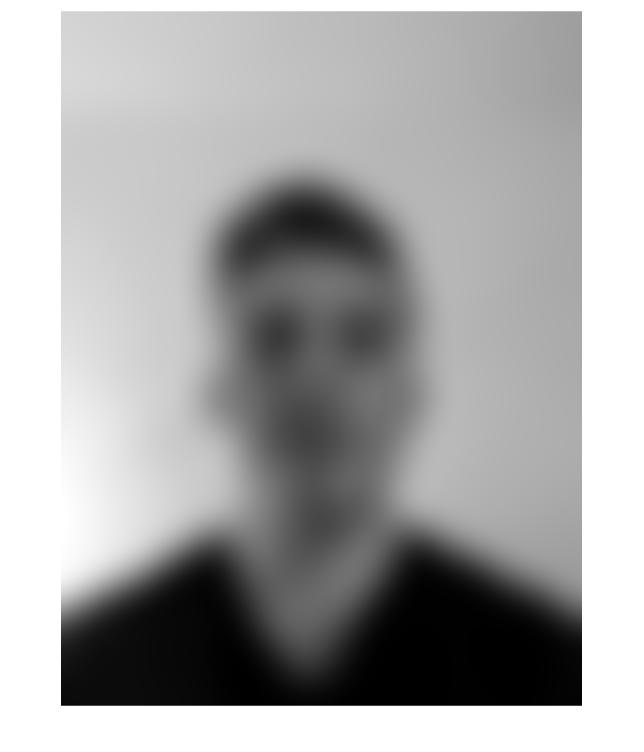

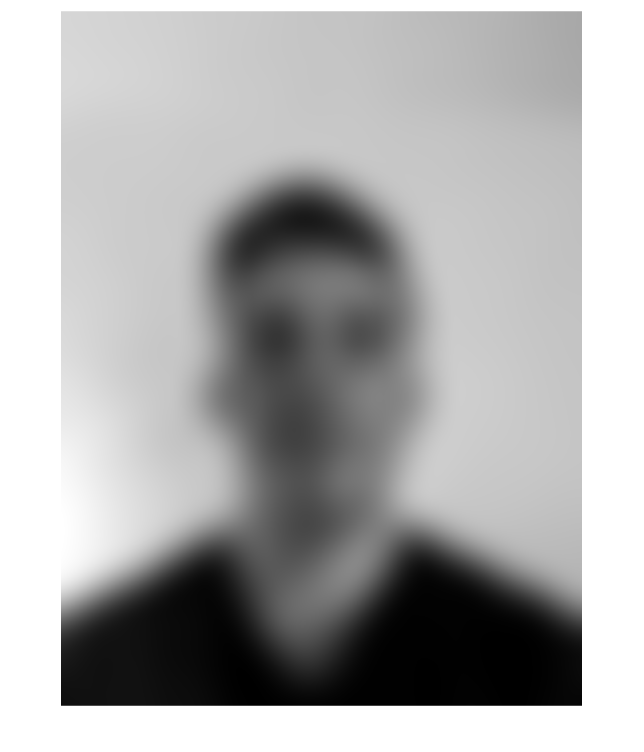

mask=double(im_fill3);
im_all_og=double(imread(imname));
sigma=100;

background_blurred_all=zeros(size(im_all));
im_new_all=zeros(size(im_all));
me_all=zeros(size(im_all));
for i=1:3
    
    background_blurred=imgaussfilt(im_all_og(:,:,i),sigma);
    
    figure()
    imshow(background_blurred(:,:),[])
    
    im_new=background_blurred;
    me=im_all_og(:,:,i).*mask;
    
    im_new(mask==1)=me(mask==1);
    im_new_all(:,:,i)=im_new;
end

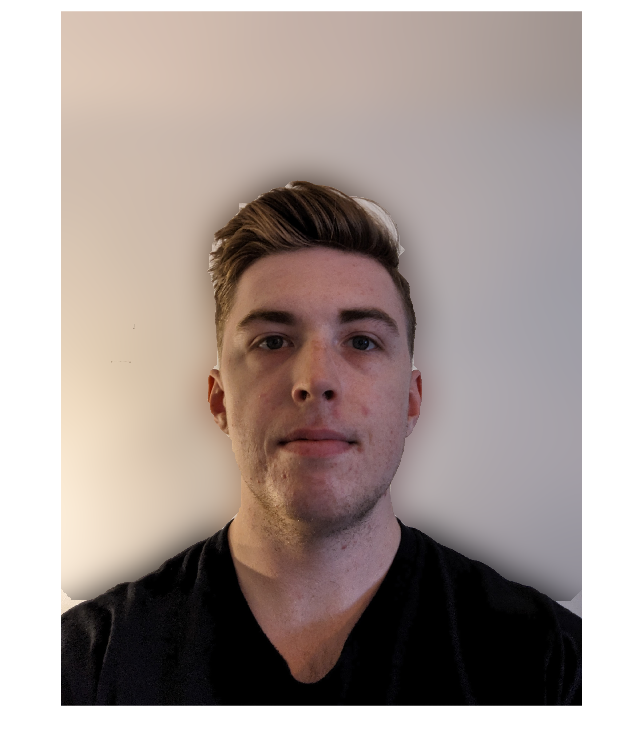

figure()
imshow(uint8(im_new_all))

## Portraite image

im_port=im_new_all;
figure()
imshow(uint8(im_port))